# Arbitrary Filter Response

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

[whaley,fs] = audioread("./data/whalesound.wav");
n = numel(whaley);
fr = (0:n-1)*(fs/n);
fr = fr(1:n/2+1);
waterabs = absorption(fr);
fabs = fr/fs*2;

## Task 1 & 5-6

The `fir2` function designs arbitrarily shaped FIR filters using the windowing method. By default, the function uses a Hamming window and has the syntax:

`b` `=` `fir2``(``order``,``freq``,``mag``)`

Given a desired filter order and normalized frequency points `freq`, `fir2` tries to design a filter with the desired magnitude `mag` at each frequency.

Larger filter orders will be closer to the desired filter but are more computationally expensive.

The designed filter isn't a great match for the desired filter. To improve the approximation, you can increase the filter order.

When you designed filters with common filter configurations, IIR filters enabled you to get a more precise approximation of the ideal filter with a lower filter order. This is also true for arbitrarily shaped filters.

The `yulewalk` function is the IIR counterpart to the `fir2` function. It uses the same inputs, but has two outputs because the IIR filter will also have `a` coefficients:

`[``b``,``a``]` `=` `yulewalk``(``order``,``freq``,``mag``)`

b = fir2(10,fabs,waterabs);
a = 1;
b = fir2(30,fabs,waterabs);
[b,a] = yulewalk(10,fabs,waterabs);

## Task 2

whalefilt = filter(b,a,whaley);

## Task 3

You can try listening to the original signal `whaley` and the filtered signal `whalefilt` with the `sound` command to hear how the filter changed the signal.

`sound``(``sig``,``fs``)`

To see how close the filter matched the desired absorption filter, you can calculate and display the magnitude response. To compare the magnitude response with the desired absorption filter, you can save the outputs from `freqz` instead of using the default display:

`[``h``,``f``]` `=` `freqz``(``b``,``a``,``n``,``fs``)`

[h,f] = freqz(b,a,[],fs);

## Task 4

`h` is a complex vector, so to visualize it you can take the absolute value first.

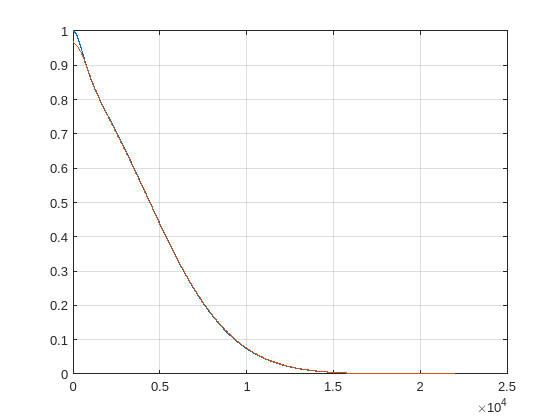

plot(fr,waterabs)
grid on
hold on
plot(f,abs(h))
hold off

% Calculating the absorption coefficent of seawater in dB / km
% CWJ for AOR Sept 2010

function [alpha] = absorption(freq,km)
    % Following Kinsler, et al "Fundamentals of Acoustics, Fourth Edition" p. 226-228.
    pH = 8; % pH
    S = 35; % salinity in ppt
    T = 5; % temperature in C
    Z = 0; % depth in km
    if nargin == 1
        km = 20;
    end
    
    f_1 = 780*exp(T/29);
    f_2 = 42000*exp(T/18);
    A = 0.083*(S/35)*exp(T/31 - Z/91 + 1.8*(pH-8));
    B = 22*(S/35)*exp(T/14-Z/6);
    C = 4.9E-10*exp(-T/26 - Z/25);
    boric_acid = A./(f_1^2+freq.^2); % contribution from boric acid
    MgSO4 = B./(f_2^2+freq.^2); % contribution from MgSO4
    hydrostatic = C; % contribution from hydrostatic pressure
    alpha = (boric_acid + MgSO4 + hydrostatic).*freq.^2;
    alpha = 10.^(-alpha*km/20); % convert from dB to linear
end